clear
clf

**Pre dimension of clamping hub with Springers**

format shortg
d_shaft_dim = [95 80 48 55 38]; % diffrent main size hubs
d_hub = 2*d_shaft_dim

d_hub =    190   160    96   110    76


additional length added for key engagement

**Bolt pretension**

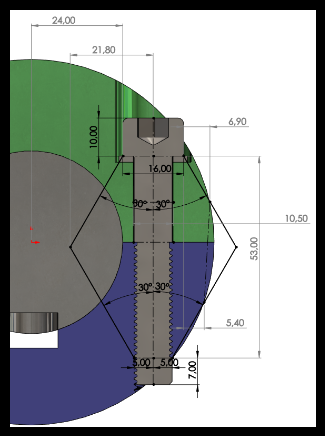

Data

bolt sizes investigated in this order

M20 M12 M10 M6

S_y = 940e6; %660;%940; %10.9 %1100  12.9; %yield strength
A_t = [245 84.3 58 20.1]*1e-6; % tensile strength cross section area
d = [0.020 0.012 0.010 0.006]; % Bolt diameter metric class
p = [0.0025 0.00175 0.0015 0.001]; %  %pitch (afstand fra top til top)
A_r = [225 76.3 52.3 17.9]*1e-6; %areal fra roddiameter se table 8-1 i shigleys eller one note
d_r = sqrt(4 * A_r / pi); % root diameteren
d_m = (d + d_r)/2;      % Mean diameter
d_p = (d + d_r)/2;      % Pitch diameter
D_Km = d * 1.3          % Mean bearing diameter at the nut or at the bolt head springer side 534

D_Km =         0.026       0.0156        0.013       0.0078


d_w = [0.030 0.018 0.016 0.010]; % M20 M12 M10 M6 bolt type ISO 4762
d_h = [0.021 0.013 0.0105 0.0064];% Hole diameter
l = p; % Amount of starting leads on thread
lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind
f = 0.18; %friktionskoefficienten i gevind
fc = 0.18; %friktionskoefficienten i spændeskive
alpha = 30; %grader %30 grader er den typiske vinkel
d_c_min = [0.021 0.013 0.0105 0.0064];%0.011 %* u.mm; %mindste diameter på spændeskive
d_c_max = [0.034 0.020 0.018 0.011] %d_c_min * 1.5%0.016 %* u.mm; %største diameter på spændeskive

d_c_max =         0.034         0.02        0.018        0.011


% d_c_min * 1.5
d_c =  (d_c_min + d_c_max) / 2; %middel diameter på spændeskive

**Finding pretension according to shigleys**

S_p = 0.85 * S_y; % proff strength
F_p = S_p * A_t; % proff force
F_i = 0.45 * F_p % n_bolts% nonperm

F_i =         88090        30310        20854         7227


**Resilience of the bolt**

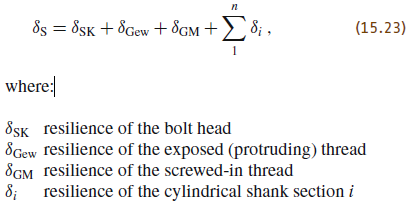

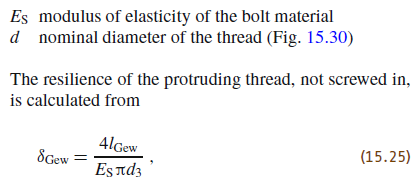

l_SK = d * 0.4 %for hexagon socket head cap screws (bolts),

l_SK =         0.008       0.0048        0.004       0.0024


E_s = 207e9;   % young modulus for the bolt for stål 207 GPa E-modul
delta_SK = 4 * l_SK./(E_s * pi * d)

delta_SK =    2.4604e-12   2.4604e-12   2.4604e-12   2.4604e-12


From here only result for M10 (3trd index) is valid

l_1 = 0.0045; %for M10 leng of parth without thread
l_Gew = 0.0226 - l_1; % length of the protruding thread (not engaged)
delta_Gew = 4 * l_Gew ./ (E_s * pi * d_r)

delta_Gew =    6.5777e-12   1.1295e-11   1.3643e-11    2.332e-11



E_M = E_s; % young modulus for the nut/hole
l_G = 0.5 * d_r % as a rule page 529. 10mm is half.

l_G =     0.0084628    0.0049282    0.0040801     0.002387


delta_G = 4 * l_G ./ (E_s * pi * d_r)

delta_G =    3.0755e-12   3.0755e-12   3.0755e-12   3.0755e-12



l_M = 0.33 * d % as a rule page 529.

l_M =        0.0066      0.00396       0.0033      0.00198


delta_M = 4 * l_M ./ (E_M * pi * d)

delta_M =    2.0298e-12   2.0298e-12   2.0298e-12   2.0298e-12



delta_GM = delta_G + delta_M

delta_GM =    5.1053e-12   5.1053e-12   5.1053e-12   5.1053e-12



% l_1 = [0.0075 0.0053 0.0060 0.003]; % full threaded
d_1 = d; % full threaded
delta_i = 4 * l_1 ./ (E_s * pi * d_1) % add one for each diameter size

delta_i =     1.384e-12   2.3066e-12   2.7679e-12   4.6132e-12



delta_S = delta_SK + delta_Gew + delta_GM + delta_i %exstendtion of the bolt

delta_S =    1.5527e-11   2.1168e-11   2.3977e-11   3.5499e-11


**Resilience of the material**

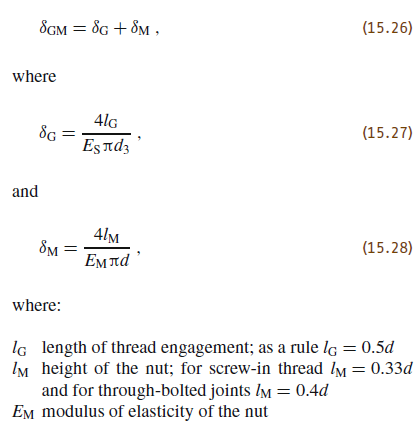

The resiliences of the individual shank areas

(15.32)

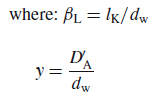

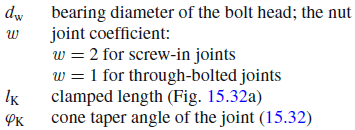

For screw in joint

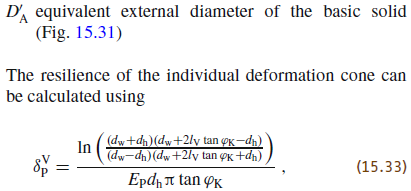

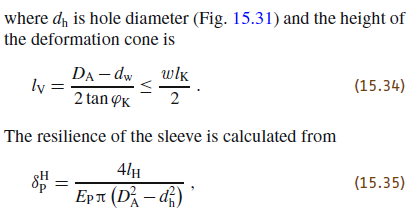

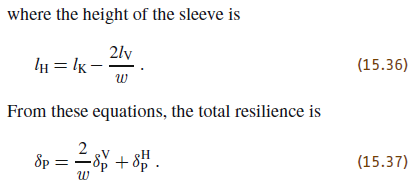

E_P = E_M

E_P =      2.07e+11


l_K = (21.8 + (53-21.8)/2)/1e3; % M10
D_A = [0.035 0.0268 0.0268 0.016]; % diameter ved tryk keglens max Fig. 15.31
% Measured in the 3D model. 
D_A_mark = [0.070 0.0298 0.0298 0.016]; 

beta_L = l_K ./ d_w

beta_L =        1.2467       2.0778       2.3375         3.74


y = D_A_mark ./ d_w

y =        2.3333       1.6556       1.8625          1.6


tan_phi_KE = 0.348 + 0.013 * log(beta_L) + 0.193 * log(y)

tan_phi_KE =       0.51439      0.45481      0.47907      0.45586


l_V = (D_A - d_w) ./ (2*tan_phi_KE) % ligning 15.34

l_V =     0.0048601    0.0096745     0.011272     0.006581



tan_phi_K = tan_phi_KE

tan_phi_K =       0.51439      0.45481      0.47907      0.45586



delta_V_P = log( ( (d_w + d_h) .* (d_w + 2.*l_V .* tan_phi_K - d_h) ) ./...
     ( (d_w - d_h) .* (d_w + 2*l_V .* tan_phi_K + d_h) ) ) ./...
     (E_P .* d_h .* pi .* tan_phi_K) % ligning 15.33

delta_V_P =    4.9582e-11   1.9905e-10   2.2761e-10   3.5264e-10


% delta_V_P = 0

l_H = (15.5 + (23+1.5)/2)/1e3; %l_k - 2*l_V/w % 15.36

delta_H_P = (4 * l_H) ./ (E_P .* pi .* (D_A.^2 - d_h.^2))

delta_H_P =    2.1771e-10   3.1077e-10   2.8074e-10   7.9375e-10



w = 2; % joint coeffecient; 2 for screw-in joints, 1 for through-bolted joints

delta_P = 2/w * delta_V_P + delta_H_P

delta_P =     2.673e-10   5.0983e-10   5.0835e-10   1.1464e-09



f_Z = (3 + 3 + 2)*1e-6 % surface roughness 10-40

f_Z =         8e-06


% springers Table 15.18

F_Z = f_Z ./ (delta_S + delta_P) % embedment in threads are found

F_Z =         28286        15066        15028       6768.8


**Tightning torque needed found with springer**

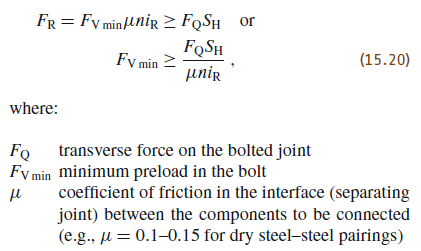

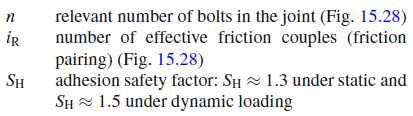

**Dynamsike krafter**

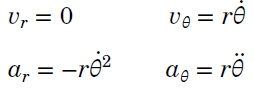

RPM = [7200 3200 1600]

RPM =         7200        3200        1600


omega = RPM / 60 * 2 * pi % angualr speed rad/s

omega =        753.98        335.1       167.55


%distance to center of mass

**top clamping piece**

Data is from solidworks

y = 0.023272; 
z = 0.00385;
r_center = sqrt(y^2 + z^2)

r_center =      0.023588


m = 1.8; % for 1kNm top peiece
a_r = r_center * omega.^2

a_r =         13410       2648.8       662.21


F_top = m * a_r

F_top =         24137       4767.9         1192


F_top_bolt = F_top/2

F_top_bolt =         12069       2383.9       595.99


**Claw piece**

y = 0.012095;
z = 0.00181;
r_center = sqrt(y^2 + z^2)

r_center =       0.01223


m = 3.6; %kg % for 1kNm claw
a_r = r_center * omega.^2

a_r =        6952.4       1373.3       343.33


F_claw = m * a_r

F_claw =         25029         4944         1236


F_claw_bolt = F_claw/2

F_claw_bolt =         12514         2472       617.99



F_A = F_claw_bolt + F_top_bolt % outer load due to centrifugal force

F_A =         24583       4855.9         1214


See that the worst case for 1kN m

is a 120 Hz, 2 pole,  FS 355 and FS 400

RPM = 7200

Torque 849

For 0.1kN m it is 120 Hz 2 pole, FS 225

RPM = 7200

Torque = 96

**Outer load**

$F_A$ - additionally loaded by an axial working load 

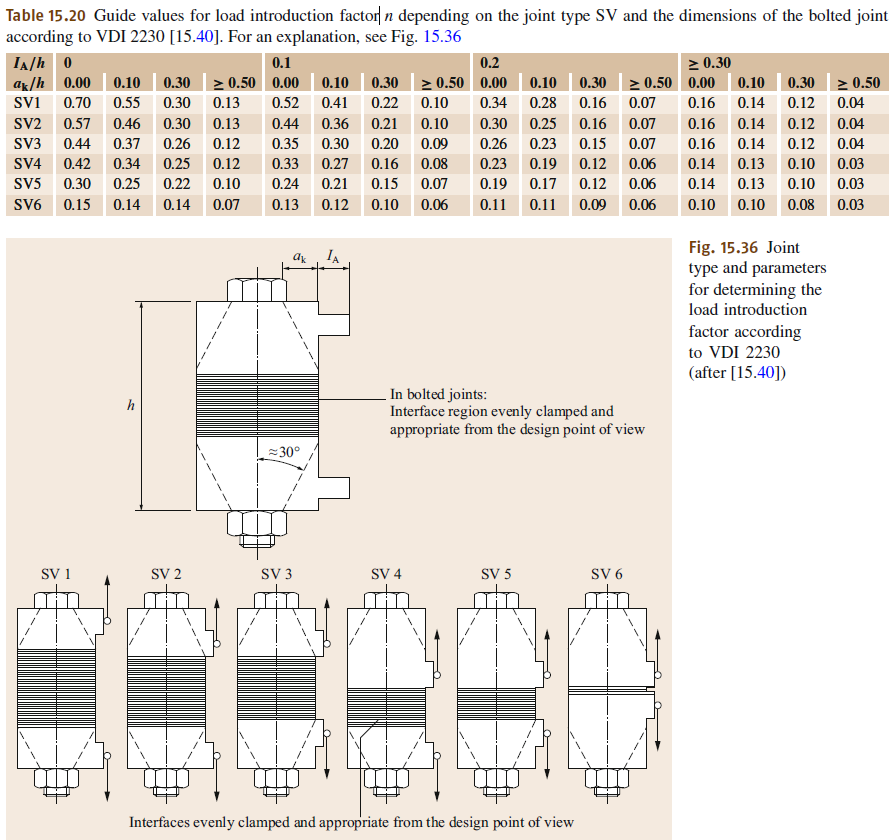

case is SV1

h = 53;
a_k = 5.4;
I_A = 24 - a_k;
I_A_h = I_A/h

I_A_h =       0.35094


a_k_h = a_k/h

a_k_h =       0.10189


n = 0.14; % is a load introduction factor from Springers table 
F_SA = n * delta_P./(delta_S + delta_P) .* F_A(1)

F_SA =        3252.7       3304.4       3286.6       3338.3


% F_Z = 0; % The resulting loss of force is called the loss of preload
F_Mmin = F_i + F_Z

F_Mmin =    1.1638e+05        45376        35882        13996


alpha_A = 1.5% tightening factor % Table 15.19: Tightening with torque wrench

alpha_A =           1.5


F_Mmax = alpha_A * F_Mmin  + F_SA% 

F_Mmax =    1.7782e+05        71369        57110        24332


f_P = F_Mmax .* delta_P

f_P =     4.753e-05   3.6386e-05   2.9032e-05   2.7894e-05


f_S = F_Mmax .* delta_S

f_S =     2.761e-06   1.5107e-06   1.3693e-06   8.6377e-07


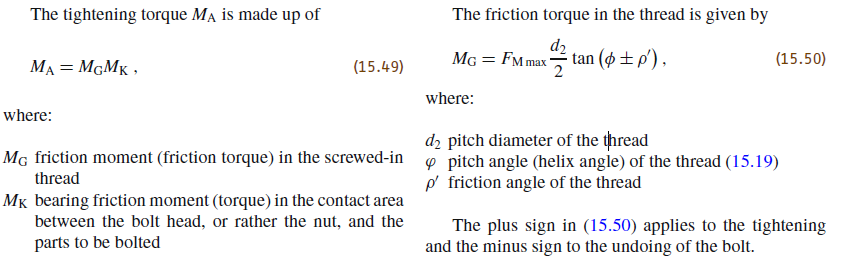

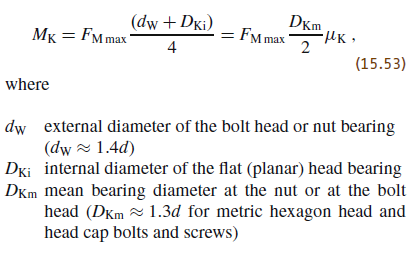

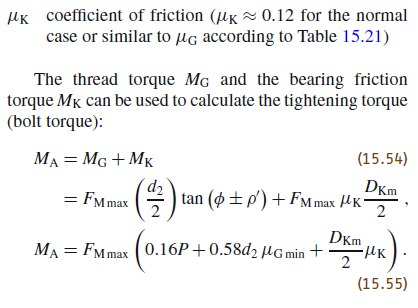

Med springer

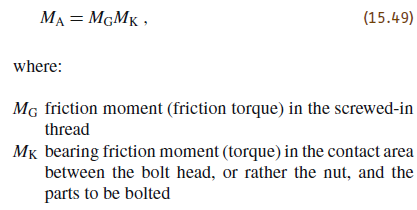

mu_G_min = 0.12; % Table 15.21 dry black tempered / steel blank
mu_K = 0.12; % for the normal case or similar to mu_G according to Table 15.21
M_A = F_Mmax .* (0.16*p + 0.58*d_p * mu_G_min + D_Km/2 * mu_K)

M_A =        577.02       141.07       94.344       24.403


Med shigleys

**a dobbelt check on how much torque the screws can take **

F_PA = F_A(1) - F_SA

F_PA =         21330        21279        21297        21245


tau_max = 940e6;
M_max_calc = tau_max / 16 * (pi * d_r.^3) % torque at max torsion

M_max_calc =        894.95       176.73       100.29       20.082


M_A

M_A =        577.02       141.07       94.344       24.403


M_max_calc > M_A

ans = 1×4 logical array
   1   1   1   0





F_i_simple = 0.75 * F_p % n_bolts% nonperm

F_i_simple =    1.4682e+05        50517        34756        12045


M_simple = 0.2 * F_i_simple .* d

M_simple =        587.26       121.24       69.513       14.454


**Normal stress under bolts**

t = [0.030 0.020 0.020 0.010]; % thickness of material under bolts
w = d_w - d_h

w =         0.009        0.005       0.0055       0.0036


% A_flade = [113e-6*4 113e-6 113e-6 113e-6]; % only taken for 1kNm small
A_flade = pi*(d_w/2).^2 - pi*(d_h/2).^2 % normal force area

A_flade =     0.0003605   0.00012174   0.00011447    4.637e-05


sigma_m = (F_Mmax - F_SA) ./ A_flade; %Normal stress
%the outer force %F_SA is only aplied when operating, and this force
% releifs the clamped material
sigma_m_mpa = sigma_m * 1e-6 

sigma_m_mpa =        484.23       559.11       470.19       452.74


**Pressure on small shafts**

L = [80 80 59 39]; % engaged length
d_small = [48 48 28 14]; %shaft diameter
A = L.*d_small % shadow area of shaft

A =         3840        3840        1652         546


F_Mmax

F_Mmax =    1.7782e+05        71369        57110        24332


sigma_shaft = F_Mmax*2 ./ A % normal stress on shaft

sigma_shaft =        92.613       37.171        69.14       89.128


Surface pressure

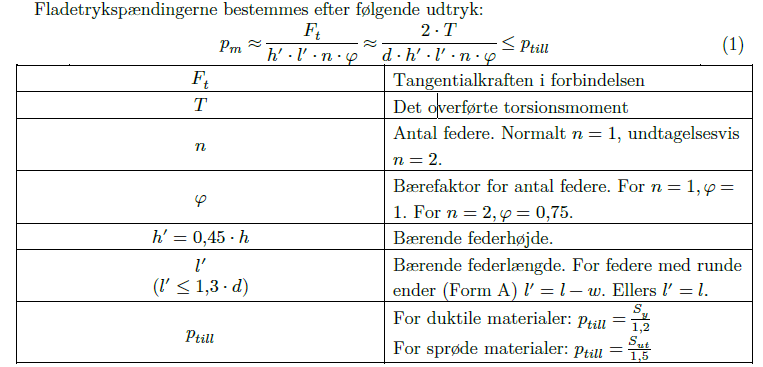

T = 1000;
d = 48e-3;
h = 9e-3;%shaft 44-50
h_mark = h * 0.45 

h_mark =       0.00405


l = 71e-3;%160e-3;
w = 14e-3/2; % only one rounding in engangement
l_mark = l -w% form a

l_mark =         0.064


p_m = 2 * T / (d * h_mark * l_mark);
p_m_MPA = p_m /1e6 %fatigue stength according to EduPack C45 normalized

p_m_MPA =        160.75


% steel is 274MPa til 317MPa
% Bevægelig not brede D10 Glidepasning for nav
% Edupack E295 annealed 217MPa - 255MPa 

AISI 1080 normalized: